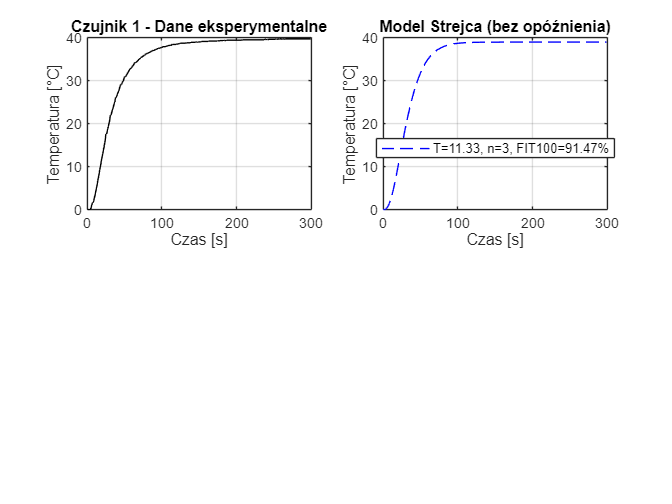


Czujnik 1:


k = 38.9525, T = 11.3311, n = 3


MSE = 258.8764, FIT100 = 91.47%


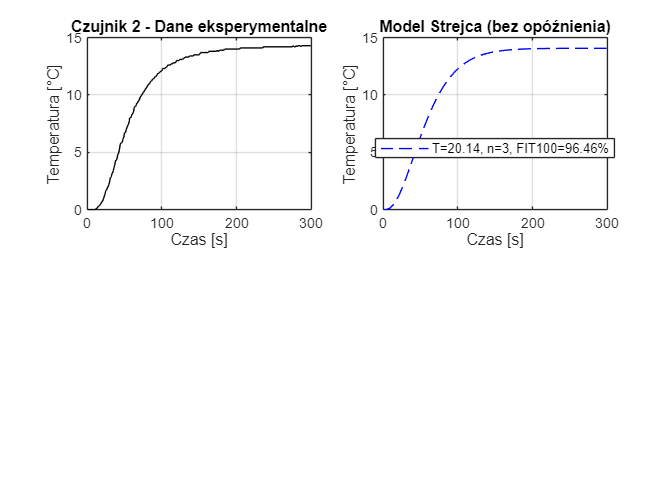


Czujnik 2:


k = 14.0700, T = 20.1434, n = 3


MSE = 8.9247, FIT100 = 96.46%


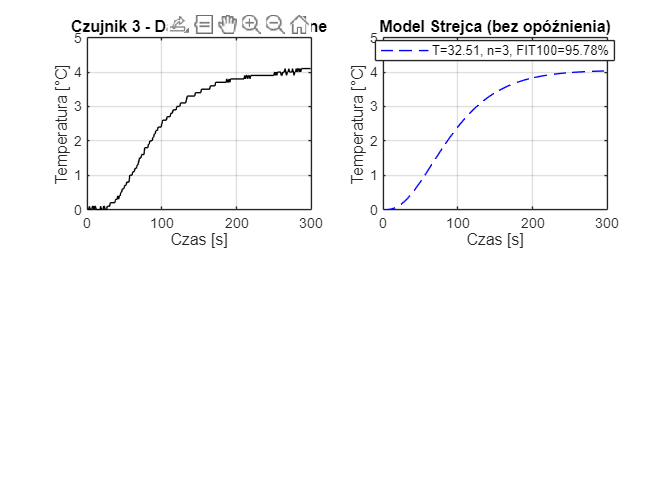


Czujnik 3:


k = 4.0532, T = 32.5140, n = 3


MSE = 1.9789, FIT100 = 95.78%


% ------------------------------
% Model Strejca (wieloinercyjny bez opóźnienia)
% ------------------------------

clear; clc; close all;
load piecyk_3_cels.mat
czas = 0:1:299;
u = ones(length(czas), 1);
n = 3;  % liczba członów inercyjnych (model Strejca)
kolory = ['r', 'g', 'b'];
nazwy = {'Czujnik 1', 'Czujnik 2', 'Czujnik 3'};

for i = 1:3
    % Dane i normalizacja
    y = piecyk_3_cels(:, i);
    y = y - y(1);
    k_static = y(end);

    % Estymacja parametrów: [k, T]
    [param, mse] = fminsearch(@(X) ident_Strejc(X, y, czas, n), [k_static, 30]);
    K = param(1); T = param(2);

    % Model Strejca
    bieguny = (-1/T) * ones(1, n);
    model = zpk([], bieguny, K / T^n);
    ym = step(model, czas);

    % Porównanie z danymi – FIT100
    Ye = iddata(y, u, 1);
    model_id = idtf(model);
    [~, fit, ~] = compare(Ye, model_id);

    % Wykresy
    figure;
    subplot(2,2,1);
    plot(czas, y, 'k');
    title([nazwy{i} ' - Dane eksperymentalne']); grid on;
    xlabel('Czas [s]'); ylabel('Temperatura [°C]');

    subplot(2,2,2);
    plot(czas, ym, 'b--');
    legenda = sprintf('T=%.2f, n=%d, FIT100=%.2f%%', T, n, fit);
    title('Model Strejca (bez opóźnienia)');
    legend(legenda, 'Location', 'best'); grid on;
    xlabel('Czas [s]'); ylabel('Temperatura [°C]');

    fprintf("\nCzujnik %d:\n", i);
    fprintf("k = %.4f, T = %.4f, n = %d\n", K, T, n);
    fprintf("MSE = %.4f, FIT100 = %.2f%%\n", mse, fit);
end


% ------------------------------
function blad = ident_Strejc(X, y, t, n)
    K = X(1); T = X(2);
    if K < 0 || T <= 0
        blad = inf; return;
    end
    bieguny = (-1/T) * ones(1, n);
    model = zpk([], bieguny, K / T^n);
    ym = step(model, t);
    blad = sum((y(:) - ym(:)).^2);
end
